%fft - dit
xn=input('Enter x[n] : ');
N=input('No of points : ');
n=length(xn);
xn=[xn zeros(1,N-n)]

xn =      1     2     1     2     1     2     0     0


y=bitrevorder(xn);
M=log2(N)

M = 3

for m=1:M
 d=2^m;
for l=1:d:N-d+1
for k=0:(d/2)-1
 v=l+k;
 w=exp(-1j*2*pi*k/d);
 b=y(v);
 c=y(v+d/2);
 y(v)=b+(w*c);
 y(v+d/2)=b-(w*c);
end
end
end
disp('X[k] by DIT FFT method : ');

X[k] by DIT FFT method : 


disp(y);

   9.0000 + 0.0000i  -1.4142 - 2.4142i   1.0000 - 2.0000i   1.4142 - 0.4142i  -3.0000 + 0.0000i   1.4142 + 0.4142i   1.0000 + 2.0000i  -1.4142 + 2.4142i



subplot(2,2,1)
stem(xn);
title('x[n]');
xlabel('Time');
ylabel('Amplitude');
subplot(2,2,2)
stem(y);

title('DIT FFT X[k]');
xlabel('Time');
ylabel('Amplitude');
subplot(2,2,3)
stem(abs(y));
title('Magnitude Response');
xlabel('Time');
ylabel('Magnitude');
subplot(2,2,4)
stem(angle(y));
title('Phase Response');
xlabel('Time');
ylabel('Phase');


%fft - dif
N=input('Enter the Point : ');
X=input('Enter the sequence : ');
n=length(X);
x=[X zeros(1,N-n)];
M=log2(N);
for m=1:M
 d=2^(M-m+1);
for l=1:d:(N-d+1)
for k=0:(d/2)-1
 w=exp(-1i*2*pi*k/d);
 z1=x(l+k);
 z2=x(l+k+d/2);
 x(l+k)=z1+z2;
 x(l+k+d/2)=(z1-z2)*w;
end
end
end
y=bitrevorder(x);
disp(y)

   9.0000 + 0.0000i  -1.4142 - 2.4142i   1.0000 - 2.0000i   1.4142 - 0.4142i  -3.0000 + 0.0000i   1.4142 + 0.4142i   1.0000 + 2.0000i  -1.4142 + 2.4142i



subplot(2,2,1)
stem(abs(X));
title('Input Sequence');
subplot(2,2,2)
stem(abs(y));
title('Magnitude Response');
subplot(2,2,3)
stem(angle(y));
title('Phase Response');
subplot(2,2,4)
stem(y);

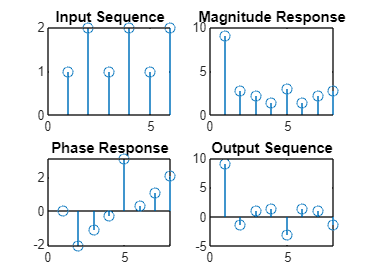

title('Output Sequence');